tri =   triangulation with properties:

              Points: [8×3 double]
    ConnectivityList: [12×3 double]


Face 1의 중심 좌표: (0.17, 0.17, 2.00)
Face 2의 중심 좌표: (-0.17, -0.17, 2.00)
Face 3의 중심 좌표: (-0.50, -0.17, 1.33)
Face 4의 중심 좌표: (-0.50, 0.17, 0.67)
Face 5의 중심 좌표: (-0.17, 0.50, 1.33)
Face 6의 중심 좌표: (0.17, 0.50, 0.67)
Face 7의 중심 좌표: (0.17, -0.17, 0.00)
Face 8의 중심 좌표: (-0.17, 0.17, 0.00)
Face 9의 중심 좌표: (0.17, -0.50, 1.33)
Face 10의 중심 좌표: (-0.17, -0.50, 0.67)
Face 11의 중심 좌표: (0.50, 0.17, 1.33)
Face 12의 중심 좌표: (0.50, -0.17, 0.67)


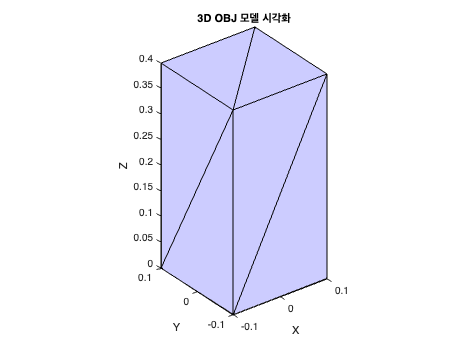

% tri = stlread('models/cube.stl')

% 
% points = tri.Points;
% connectivityList = tri.ConnectivityList;
% 
% numFaces = size(connectivityList, 1);
% for i= 1:numFaces
%     faceIndices = connectivityList(i, :);
% 
%     faceVertices = points(faceIndices, :);
% 
%     faceCenter = mean(faceVertices, 1);
%     fprintf('Face %d의 중심 좌표: (%.2f, %.2f, %.2f)\n', i, faceCenter);
% end

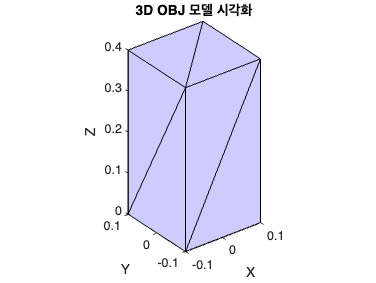

clear;

mesh = readObj('data/models/cube_checker.obj');

% 정점과 Face 데이터를 가져오기
vertices = mesh.v; 
faces = mesh.f.v;  % f 구조체 내부의 정점 인덱스

figure;
trisurf(faces, vertices(:,1), vertices(:,2), vertices(:,3), ...
        'FaceColor', [0.8 0.8 1], 'EdgeColor', 'k');
axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('3D OBJ 모델 시각화');
view(3); % 🚀 3D 모드 활성화
rotate3d on; % 🚀 마우스로 회전 가능하게 설정

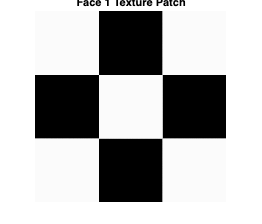

%% 1️⃣ 데이터 준비
clc; clear; close all;

mesh = readObj('data/models/cube_checker.obj');

% 텍스처 이미지 로드
I = imread('data/models/1.png');  % 텍스처 이미지 파일을 맞게 변경

% 시각화할 특정 Face 번호 선택 (1~12)
face_idx = 1;

%% 2️⃣ Face의 UV 인덱스 가져오기
uv_idx = mesh.f.vt(face_idx, :);  % 해당 Face의 UV 좌표 인덱스 (3개)

%% 3️⃣ UV 좌표 추출
uv_coords = mesh.vt(uv_idx, :);  % (3x2) 크기의 UV 좌표 (U, V)

%% 4️⃣ UV 좌표를 이미지 픽셀 좌표로 변환
[imgH, imgW, ~] = size(I);  % 이미지 크기 가져오기
pixel_coords = round(uv_coords .* [imgW, imgH]);  % UV를 픽셀 좌표로 변환

%% 5️⃣ Bounding Box 계산
x_min = max(1, min(pixel_coords(:, 1)));
x_max = min(imgW, max(pixel_coords(:, 1)));
y_min = max(1, min(pixel_coords(:, 2)));
y_max = min(imgH, max(pixel_coords(:, 2)));

%% 6️⃣ 해당 영역의 텍스처 추출
cropped_texture = I(y_min:y_max, x_min:x_max, :);

%% 7️⃣ 결과 출력
figure;
imshow(cropped_texture);
title(['Face ' num2str(face_idx) ' Texture Patch']);

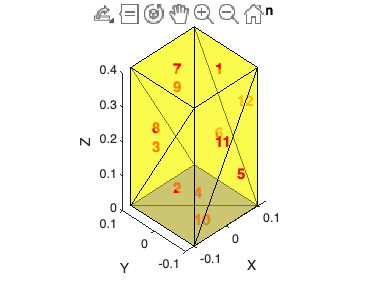

%% 1️⃣ 3D 메시 플로팅하여 Face 인덱스 확인
clc; clear; close all;
mesh = readObj('data/models/cube_checker.obj');

% Figure 생성
figure;
hold on;
trisurf(mesh.f.v, mesh.v(:,1), mesh.v(:,2), mesh.v(:,3), 'FaceAlpha', 0.5);
axis equal;
title('Face Index Visualization');
xlabel('X'); ylabel('Y'); zlabel('Z');
view(3);

% Face 중앙에 Face 번호 표시
for i = 1:12
    % 현재 Face의 정점 3개 가져오기
    face_vertices = mesh.v(mesh.f.v(i, :), :);
    
    % Face의 중심 좌표 계산
    face_center = mean(face_vertices, 1);
    
    % Face의 중앙에 번호 표시
    text(face_center(1), face_center(2), face_center(3), num2str(i), ...
        'FontSize', 12, 'FontWeight', 'bold', 'Color', 'r');
end

hold off;

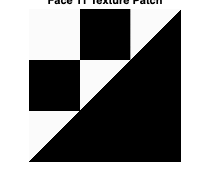

%% 1️⃣ 데이터 준비
clc; clear; close all;

mesh = readObj('data/models/cube_checker.obj');

% 텍스처 이미지 로드
I = imread('data/models/1.png');  % 텍스처 이미지 파일을 맞게 변경

% 시각화할 특정 Face 번호 선택 (1~12)
face_idx = 11;

%% 2️⃣ Face의 UV 인덱스 가져오기
uv_idx = mesh.f.vt(face_idx, :);  % 해당 Face의 UV 좌표 인덱스 (3개)

%% 3️⃣ UV 좌표 추출
uv_coords = mesh.vt(uv_idx, :);  % (3x2) 크기의 UV 좌표 (U, V)

%% 4️⃣ UV 좌표를 이미지 픽셀 좌표로 변환
[imgH, imgW, ~] = size(I);  % 이미지 크기 가져오기
pixel_coords = round(uv_coords .* [imgW, imgH]);  % UV를 픽셀 좌표로 변환

%% 5️⃣ Bounding Box 계산 (삼각형이 포함된 최소 영역)
x_min = max(1, min(pixel_coords(:, 1)));
x_max = min(imgW, max(pixel_coords(:, 1)));
y_min = max(1, min(pixel_coords(:, 2)));
y_max = min(imgH, max(pixel_coords(:, 2)));

% 잘라낼 텍스처 영역
cropped_texture = I(y_min:y_max, x_min:x_max, :);

%% 6️⃣ 삼각형 마스크 생성 (해당 Face만 표시)
[X, Y] = meshgrid(x_min:x_max, y_min:y_max);
mask = inpolygon(X, Y, pixel_coords(:, 1), pixel_coords(:, 2));  % 삼각형 내부 마스크

% 마스크를 3채널(RGB)로 확장
mask_3d = repmat(mask, [1, 1, size(I, 3)]);

% 삼각형 내부는 원래 텍스처 값 유지, 나머지는 검은색(0)
cropped_texture(~mask_3d) = 0;

%% 7️⃣ 결과 출력 (해당 Face만 표시)
figure;
imshow(cropped_texture);
title(['Face ' num2str(face_idx) ' Texture Patch']);

clear;

mesh = readObj('data/models/cube_checker.obj');

% 구조체 생성
mesh_data.vertices = mesh.v;  % 정점(Vertex)
mesh_data.faces = mesh.f;        % 면(Face)
mesh_data.uv_coords = mesh.vt; % 텍스처 좌표

% Simulink.Bus 객체로 변환
bus_info = Simulink.Bus.createObject(mesh_data);
bus_name = bus_info.busName;

% MAT 파일로 저장
save('triangle_mesh_bus.mat', 'mesh_data');